Let us first define the system's global parameters:

rate = 30000;
delta_x = 1 / rate;

First, read the audio file encoded in mp3

% Step 1: Read the audio file
[audio, fs] = audioread("data/the-second-waltz-.mp3");
% sound(audio(:, 1), fs);
plot_signal(audio(:, 1), "original piece", delta_x, length(audio))

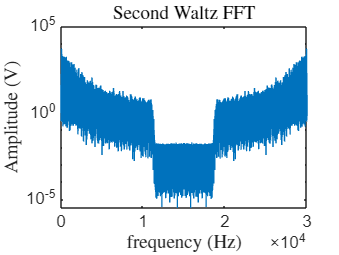

audio_fft = fft(audio(:, 1));
plot_signal_fft(audio_fft, "Second Waltz FFT", delta_x, length(audio_fft));

sound(audio(1: 1000000), fs)
audio_original = audio(1: 6904507);
save('original_audio.mat', 'audio_original')

function plot_signal_fft(signal_fft, header, delta_x, num_samples)
    fft_to_show = abs(signal_fft) / (2 * pi);
    f = 1 / (delta_x * num_samples) * linspace(0, (num_samples - 1), num_samples);
    plot(f, fft_to_show);
    set(gca, 'yscale', 'log');
    xlabel("frequency (Hz)", Interpreter="latex");
    ylabel("Amplitude (V)", Interpreter="latex");
    title(header, Interpreter="latex");
end

function plot_signal(signal, header, delta_x, num_samples)
    t = linspace(0, delta_x * (num_samples - 1), num_samples);
    plot(t, signal, Color="#D95319");
    xlabel("Time (s)", Interpreter="latex");
    ylabel("Amplitude (V)", Interpreter="latex");
    title(header, Interpreter="latex");
end